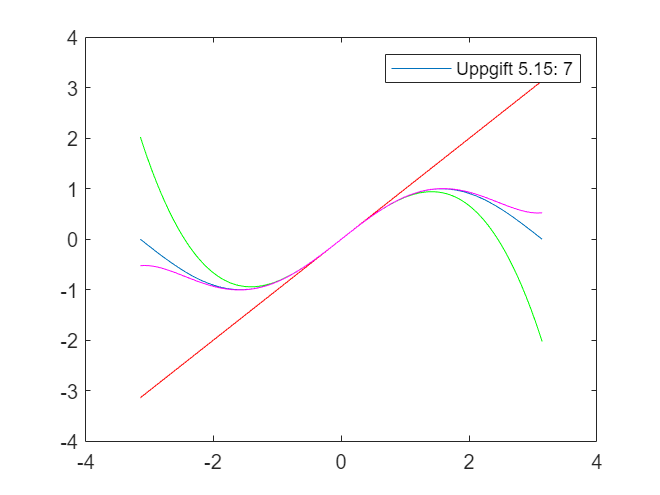

% 5.15 7
clear;
x = linspace(-pi, pi);
ySin = sin(x);
y1 = x;
y3 = x - (x.^3)/6;
y5 = y3 + (x.^5)/120;

plot(x,ySin)
hold on;
plot(x,y1,'-r');
plot(x,y3,'-g');
plot(x,y5,'-m');
legend("Uppgift 5.15: 7");

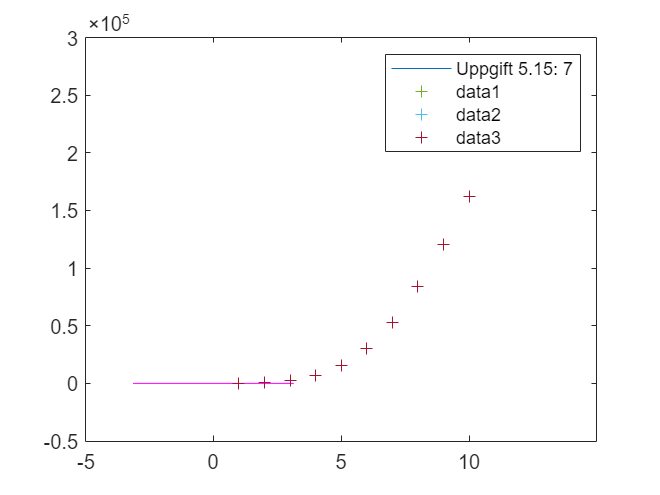

% 5.15 8 a
clear;
t = linspace(1,12,12);
N = [97 709 2698 6928 15242 29944 52902 83903 120612 161711 206247 257085];

plot(t,N,'+');
semilogy(t,N,'+');
loglog(t,N,'+');

% 5.15 8 b
clear;
t = [0 2 4 6 8 10 12 14];
N = [2 5 10 20 40 109 200 403]

N =      2     5    10    20    40   109   200   403


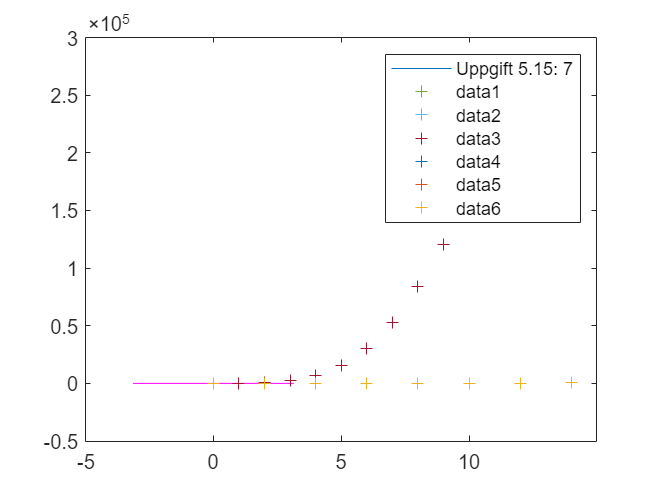

plot(t,N,'+');
semilogy(t,N,'+');
loglog(t,N,'+');

% 5.15 16
clear;
z = linspace(-50,50);
pA = z.^5 - 1.1;
pB = z.^2+3*z+4;
pC = z.^2+(-1+1i)*z+2-2i;

plot(z, pA);
hold on;
plot(z, pB);
plot(z, pC);

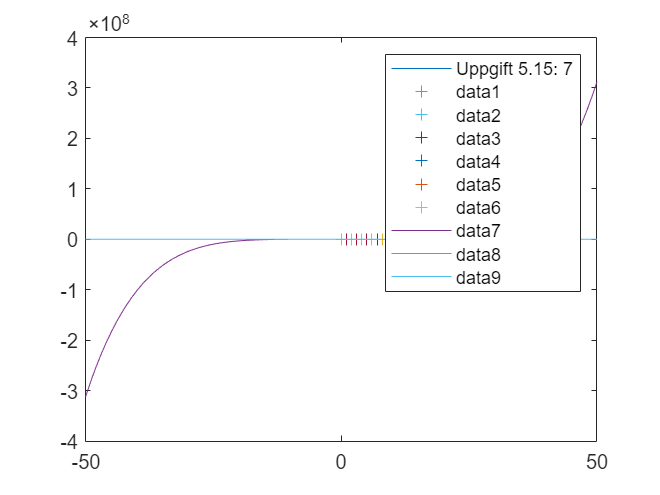

hold off;

[MinA, IndexA] = min(abs(pA))

MinA = 1.0671

IndexA = 51

[MinB, IndexB] = min(abs(pB))

MinB = 1.7502

IndexB = 49

[MinC, IndexC] = min(abs(pC))

MinC = 2.3016

IndexC = 51

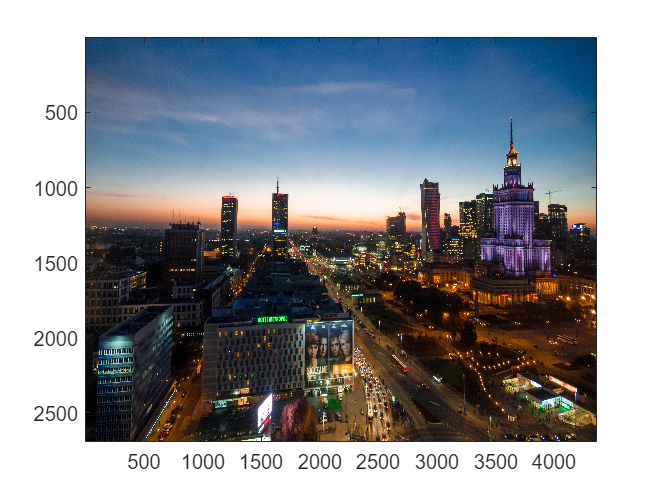

% 5.15 19
clear;
%[url_img, map] = imread('https://static.pexels.com/photos/14621/Warsaw-at-night-free-license-CC0.jpg');
A = imread('https://static.pexels.com/photos/14621/Warsaw-at-night-free-license-CC0.jpg');
%figure, imshow(url_img), title('Image from url')
imagesc(A);

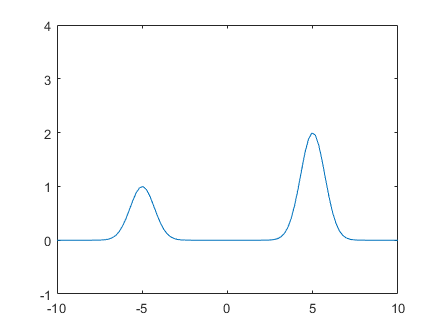

% 5.15 21
clear
x = linspace(-10,10);

f1 = @(x) exp(-(x+5).^2);
f2 = @(x) 2*exp(-(x-5).^2);

plot(x, f1(x) + f2(x))
axis([-10 10 -1 4])

frames = moviein(101);

for i = 1:101
    t = 0.1*(i-1);
    plot(x, f1(x-t) + f2(x+t));
    axis([-10 10 -1 4])
    frames(:,i) = getframe;
end    
movie(frames, 10)
vidObj = VideoWriter('animering.avi');
open(vidObj);
writeVideo(vidObj,frames);
close();


% 6.18 9
clear
x = input('Input your x: ')

x = 10

y = input('Input your y: ')

y = 155


v = [x, y];

if x == 0 && y > 0
    ang = pi/2;
elseif x == 0 && y < 0
    ang = -pi/2
elseif x > 0
    ang = atan(y/x);
elseif x < 0 || y >= 0
    ang = atan(y/x) + pi;
elseif x < 0 || y <= 0
    ang = atan(y/x) - pi;
end
ang

ang = 1.5064

angle(x+i*y)

ans = 1.5064

% 6.18 14
clear
f0 = 0;
f1 = 1;
fRes = f0 + f1;
counter = 2;
while fRes < 100000
    f0 = f1;
    f1 = fRes;
    fRes = f0 + f1;
    counter = counter+1;
end
counter

counter = 26

fRes

fRes = 121393

% 6.18 27 a
clear
v = [1 -2 -3 -4 2 3 4]

v =      1    -2    -3    -4     2     3     4


minsta = 1e30;
n = length(v);
for i = 1:n
    if v(i) < minsta
        minsta = v(i);
        pos = i;
    end
end
disp('Minsta värde'), disp(minsta)

Minsta värde
    -4



disp('Position'), disp(pos)

Position
     4



% 6.18 27 b
clear
v = [1 -2 -3 -4 2 3 4]

v =      1    -2    -3    -4     2     3     4


storsta = 1e-30;
n = length(v);
for i = 1:n
    if v(i) > storsta
        storsta = v(i);
        pos = i;
    end
end
disp('Storsta värde'), disp(storsta)

Storsta värde
     4



disp('Position'), disp(pos)

Position
     7



% 6.18 27 c
clear
n = input('Input your rows: ')

n = 23

m = input('Input your columness: ')

m = 32

v = rand(n, m)

v =     0.7294    0.9496    0.9546    0.8844    0.1038    0.8061    0.9074    0.9608    0.6409    0.4481    0.6201    0.1019    0.8752    0.6028    0.8875    0.1366    0.3098    0.8547    0.7368    0.2699    0.0655    0.0076    0.2509    0.1708    0.5477    0.4160    0.6949    0.0869    0.2442    0.2203    0.7467    0.3564
    0.4823    0.7740    0.8146    0.0198    0.7991    0.3778    0.0943    0.2229    0.5037    0.8306    0.1560    0.6446    0.6590    0.5915    0.9005    0.2997    0.6811    0.2656    0.1746    0.9494    0.3608    0.9890    0.0661    0.8232    0.9918    0.4391    0.3104    0.5489    0.4382    0.3786    0.4879    0.0544
    0.3381    0.6361    0.6233    0.3427    0.9029    0.5180    0.1813    0.3956    0.9380    0.1267    0.3984    0.9801    0.7876    0.2253    0.4480    0.7614    0.9341    0.9339    0.3554    0.9022    0.2581    0.2016    0.7272    0.5871    0.4834    0.7844    0.3435    0.3177    0.7351    0.4228    0.7924    0.9141
    0.2368    0.7536    0.3283   

minsta = 1e30;
for i = 1:n %rows
    for j = 1:m %cols
        if v(i, j) < minsta
            minsta = v(i, j);
            pos = [i, j];
        end
    end
end
disp('Minsta värde'), disp(minsta)

Minsta värde
   7.3934e-05



disp('Position'), disp(pos)

Position
     8    27



% 6.18 27 d
clear
n = input('Input your rows: ')

n = 23

m = input('Input your columness: ')

m = 23

d = input('Input your depth: ')

d = 23

v = rand(n, m, d)

v = v(:,:,1) =

    0.8367    0.4172    0.7892    0.2112    0.2404    0.0494    0.3554    0.2785    0.9102    0.5151    0.6937    0.0153    0.5123    0.6511    0.8943    0.9477    0.1804    0.2689    0.3939    0.0487    0.3960    0.1034    0.9635
    0.2206    0.8158    0.4983    0.7003    0.9613    0.2010    0.6407    0.5905    0.9121    0.4818    0.1989    0.7507    0.8550    0.3511    0.3003    0.0301    0.3699    0.1936    0.3402    0.9788    0.5323    0.2964    0.8449
    0.8060    0.8048    0.4370    0.9562    0.9236    0.4991    0.8279    0.2874    0.6295    0.4459    0.4524    0.0621    0.4654    0.3126    0.7151    0.4411    0.2052    0.0641    0.3565    0.6323    0.9036    0.7990    0.7531
    0.2486    0.3604    0.1684    0.6355    0.2742    0.2754    0.0446    0.9199    0.1315    0.7982    0.7889    0.4317    0.2648    0.2743    0.3304    0.7007    0.0956    0.4254    0.3730    0.0726    0.3400    0.4417    0.7030
    0.9983    0.9138    0.2646    0.8913    0.2233    0.4196

minsta = 1e30;
for i = 1:n %rows
    for j = 1:m %cols
        for k = 1:d
            if v(i, j, k) < minsta
                minsta = v(i, j, k);
                pos = [i, j, k];
            end
        end
    end
end
disp('Minsta värde'), disp(minsta)

Minsta värde
   4.8345e-05



disp('Position'), disp(pos)

Position
     5    21    11

